clc
clear all
close all;

load data

load('PlaceCells_demo_data.mat')
tBinSz_sm = 200; % decoding window tau, 200ms
fx_placefield = fx_placefield+ (eps.^8); %f(x), Add a small number so there are no zeros
cellnum = length(fx_placefield(1,:)); % number of cellsm, N
expecSpk = fx_placefield.*tBinSz_sm./1000; %Expected number of spikes per bin,i.e. tau*f(x)

bin-by-bin decoding

timevec = 0:tBinSz_sm/1000:max(truex_position(:,1));% time vector
pMat_all = [];% to save the posterior probablity matrix
currentpos_all = [];% to save the current positions

% time bin loop
for i = 1:length(timevec)
    bin = timevec(i);% current time
    [~,avglindist_bin] = min(abs(truex_position(:,1) - bin));% current position ID
    avglindist = truex_position(avglindist_bin(1),2);% current position
   
    % get all the spikes in the current bin
    clear spikecount
    celldata = [];
    for n = 1:cellnum
        spikes_i  = y_spiketrain(find(y_spiketrain(:,1) == n),2);%spikes of the current cell
        if ~isempty(spikes_i)
            spikebins = spikes_i(find(spikes_i >= (bin - tBinSz_sm/2000) & spikes_i <= (bin + tBinSz_sm/2000)));
            spikecount(n) = length(spikebins);
            tmpcelldata = [length(spikebins),n];
        else
            tmpcelldata = [0,n];
            spikecount(n) = 0;
        end
        celldata = [celldata;tmpcelldata];
    end
    
    cellcounts = sum((spikecount > 0));
    if (cellcounts > 0) % decode the bin that has spikes
        cellsi = find(spikecount > 0);%active cell
        spkPerBin = celldata(cellsi,1)'; % spike counts per bin
        
        fx_placefield_active = fx_placefield(:,cellsi);% f(x)
        nPBin = size(fx_placefield_active,1); % N position bin
        wrking = bsxfun(@power, fx_placefield_active, spkPerBin); %f(x)^y
        wrking = prod(wrking,2);%prod(f(x)^y)
        expon = exp(-sum(expecSpk,2)); %e^-sum(tau*f(x))
        pMat = bsxfun(@times,wrking, expon); %prod(f(x)^y) * e^-sum(tau*f(x))
        pMat(isnan(pMat)) = 0; % set empty bins to zero
        pMat = pMat./sum(pMat);% C(x), normalization to make sure sum(p(x|y))=1
        %hence, pMat is the posterior probability matrix p(x|y) = C*prod(f(x)^y) * e^-sum(tau*f(x))
        pMat_all = [pMat_all,pMat];% pMat is the decoding result for each bin, and pooled into pMat_all
        currentpos_all = [currentpos_all,avglindist];% save current postion
    end
end

visualization of the decoding result

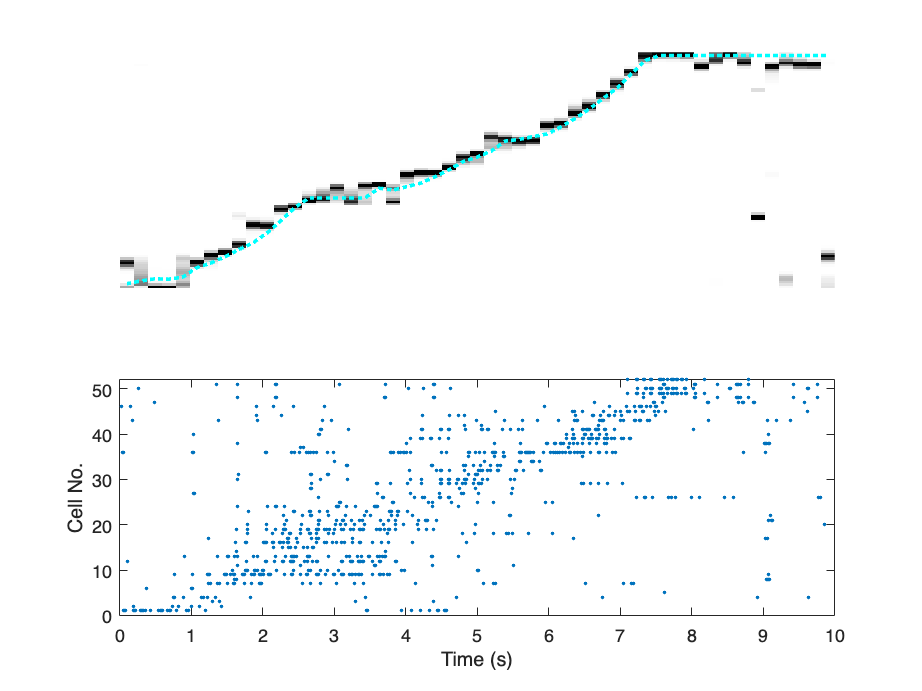

figure,
subplot(211)
imagesc(-1.*pMat_all) %reverse the axis
ax = gca;
ax.YDir = 'normal';
hold on
colormap(gray)
plot(currentpos_all/2,':','color','cyan','linewidth',2)
caxis([-0.3,0])%probability 0-0.3
axis off
subplot(212)
running_ID = find(y_spiketrain(:,2)>0);
plot(y_spiketrain(running_ID,2),y_spiketrain(running_ID,1),'.')
xlim([0,max(timevec)])
ylim([0,cellnum])
xlabel('Time (s)')
ylabel('Cell No.')

visualization of the decoding error

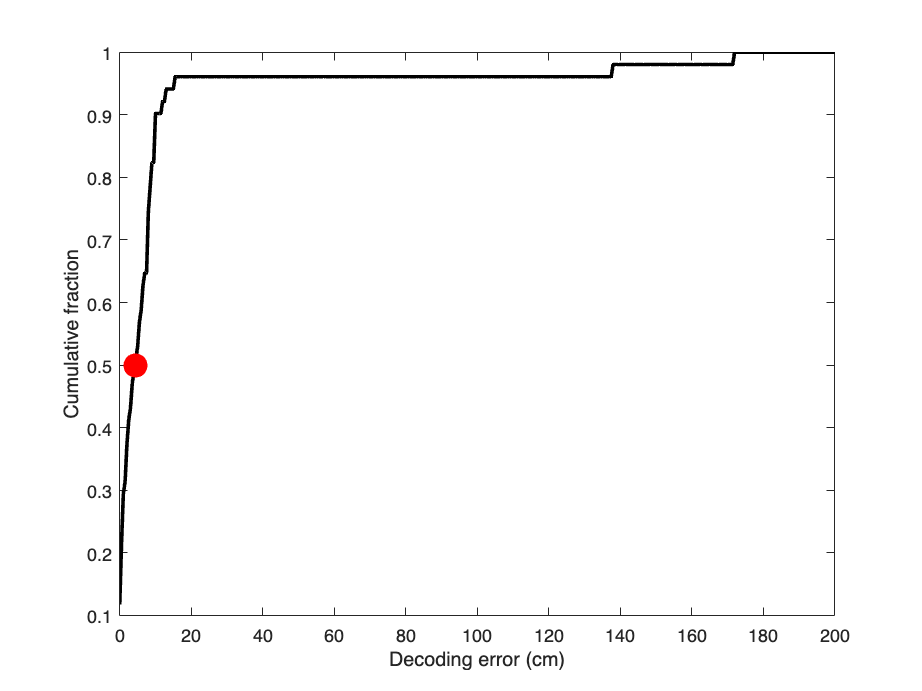

[~,estimated_posID] = max(pMat_all);
estimated_pos = x_position(estimated_posID)';
decode_error = abs(estimated_pos-currentpos_all);
figure,
counts = hist(decode_error,0:0.5:200);
plot(0:0.5:200,cumsum(counts)./sum(counts),'k','linewidth',2) % cumulative histogram
hold on
plot(median(decode_error),0.5,'r.','markersize',40) % median decoding error
hold off
xlabel('Decoding error (cm)')
ylabel('Cumulative fraction')